ACA_st.name='ACA';
ACA_st.lat=44.38;
ACA_st.lon=-68.26;
ACA_st.alt=157;
ACA_st.env='coast';
ACA_st.footp='RB'

ACA_st = struct with fields:
     name: 'ACA'
      lat: 44.3800
      lon: -68.2600
      alt: 157
      env: 'coast'
    footp: 'RB'



ACA_rd=read_betsy('ACA_head',ACA_st.name);

datevec(ACA_rd.Time(1))

ans =         1993           4           2           0           0           0

datevec(ACA_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(ACA_rd.U_S,[5 50 95])

ans =    45.8292   74.7900   98.1557

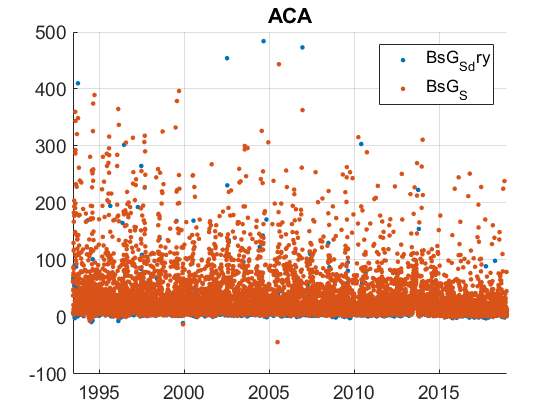

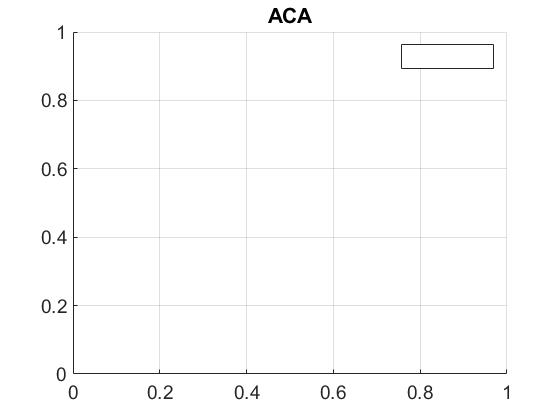

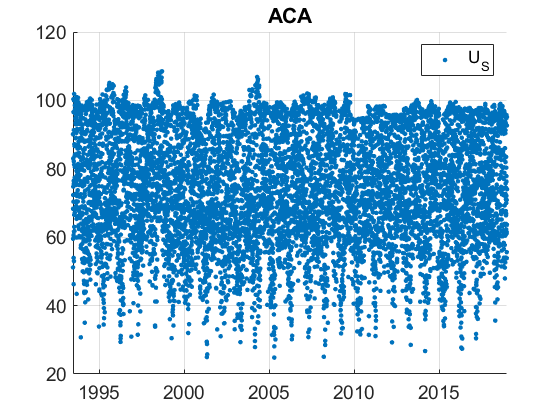

plotFigControl(ACA_rd,ACA_st.name);

% 1 size cut, ok
% sc: ok, cycle not so clear, few negatives




% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE=[467;530;660]*ones(1,4);
% % ACA_cal=compute_exp_SSA(ACA_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(ACA_cal);

%Questions:
%problems:
% higher minimal values in summer 2013 ?


ACA_tr=ACA_rd;
ACA_tr.y=year(ACA_tr.Time);
%eneleve une valeur de 2019
ACA_tr=ACA_tr(1:end-1,:);
% begin at the beginning of a year: 1994
%end: 2018
P=timerange('1994-01-01','2019-01-01');
ACA_tr=ACA_tr(P,:);

names=fieldnames(ACA_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    ACA_tr.(N{i})=[];
end
% 21.6.2013 to 1.10.2013 to delete
P=timerange('2013-06-20','2013-09-30');
% ACA_tr.BsG_S(P)=NaN;
ACA_tr.BsG_S_dry(P)=NaN;

Iterating trend, loop:2, trend: -0.0016662/day = -0.60859/year
Iterating trend, loop:3, trend: -0.0016262/day = -0.59395/year
Iteration stopped, trend: -0.0016261/day = -0.59393/year
Final estimate on noise autocorrelation=0.049432, Noise standard deviation:7.9429
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0019152  -0.0013612]/day = [-0.69953    -0.49719]/yr
Round:200/500, Trend BCI: [-0.0019407  -0.0013416]/day = [-0.70886    -0.49002]/yr
Round:300/500, Trend BCI: [-0.0019389  -0.0013331]/day = [-0.70818    -0.48691]/yr
Round:400/500, Trend BCI: [-0.0019384  -0.0013133]/day = [-0.70801    -0.47968]/yr
Round:500/500, Trend BCI: [-0.001931   -0.001309]/day = [-0.70528    -0.47812]/yr
Trend BCI: [-0.001931   -0.001309]/day = [-0.70528    -0.47812]/yr
Iterating trend, loop:2, trend: -0.00095953/day = -0.35047/year
Iterating trend, loop:3, trend: -0.00095534/day = -0.34894/year
Iteration stopped, trend: -0.00095534/day = -0.34894/year
Final estimate on noise autocorrelation=0.0

Iterating trend, loop:2, trend: -0.0021661/day = -0.79116/year
Iterating trend, loop:3, trend: -0.0021455/day = -0.78365/year
Iteration stopped, trend: -0.0021455/day = -0.78365/year
Final estimate on noise autocorrelation=0.10616, Noise standard deviation:4.8928
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.003044  -0.0013444]/day = [-1.1118    -0.49106]/yr
Round:200/500, Trend BCI: [-0.0030584  -0.0012701]/day = [-1.1171     -0.4639]/yr
Round:300/500, Trend BCI: [-0.0030731  -0.0012839]/day = [-1.1224    -0.46894]/yr
Round:400/500, Trend BCI: [-0.0030731  -0.0012242]/day = [-1.1224    -0.44713]/yr
Round:500/500, Trend BCI: [-0.0030499  -0.0012242]/day = [-1.114    -0.44713]/yr
Trend BCI: [-0.0030499  -0.0012242]/day = [-1.114    -0.44713]/yr


Iterating trend, loop:2, trend: -0.00073118/day = -0.26706/year
Iterating trend, loop:3, trend: -0.00071561/day = -0.26138/year
Iteration stopped, trend: -0.00071558/day = -0.26136/year
Final estimate on noise autocorrelation=0.1255, Noise standard deviation:5.5261
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0020241  0.00031485]/day = [-0.7393       0.115]/yr
Round:200/500, Trend BCI: [-0.0019342  0.00032323]/day = [-0.70645     0.11806]/yr
Round:300/500, Trend BCI: [-0.001885  0.00033199]/day = [-0.68849     0.12126]/yr
Round:400/500, Trend BCI: [-0.0018069  0.00036361]/day = [-0.65997     0.13281]/yr
Round:500/500, Trend BCI: [-0.0017803  0.00036361]/day = [-0.65025     0.13281]/yr
Trend BCI: [-0.0017803  0.00036361]/day = [-0.65025     0.13281]/yr


Iterating trend, loop:2, trend: -0.00048182/day = -0.17598/year
Iterating trend, loop:3, trend: -0.00041826/day = -0.15277/year
Iteration stopped, trend: -0.00041813/day = -0.15272/year
Final estimate on noise autocorrelation=0.08171, Noise standard deviation:6.1468
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0016851  0.00076377]/day = [-0.61547     0.27897]/yr
Round:200/500, Trend BCI: [-0.0017056  0.00074236]/day = [-0.62298     0.27115]/yr
Round:300/500, Trend BCI: [-0.0017542  0.00073482]/day = [-0.64073     0.26839]/yr
Round:400/500, Trend BCI: [-0.0016362  0.00073482]/day = [-0.59763     0.26839]/yr
Round:500/500, Trend BCI: [-0.0016158  0.00074872]/day = [-0.59017     0.27347]/yr
Trend BCI: [-0.0016158  0.00074872]/day = [-0.59017     0.27347]/yr


Iterating trend, loop:2, trend: -0.00047272/day = -0.17266/year
Iterating trend, loop:3, trend: -0.00059277/day = -0.21651/year
Iteration stopped, trend: -0.00059343/day = -0.21675/year
Final estimate on noise autocorrelation=0.061648, Noise standard deviation:6.0069
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0017508  0.00063812]/day = [-0.63949     0.23307]/yr
Round:200/500, Trend BCI: [-0.0016529  0.00061904]/day = [-0.60373     0.22611]/yr
Round:300/500, Trend BCI: [-0.0017  0.00057384]/day = [-0.62093     0.20959]/yr
Round:400/500, Trend BCI: [-0.0016842  0.00061947]/day = [-0.61515     0.22626]/yr
Round:500/500, Trend BCI: [-0.0016788  0.00061947]/day = [-0.61319     0.22626]/yr
Trend BCI: [-0.0016788  0.00061947]/day = [-0.61319     0.22626]/yr


Iterating trend, loop:2, trend: -0.0012701/day = -0.46391/year
Iterating trend, loop:3, trend: -0.0013742/day = -0.50193/year
Iteration stopped, trend: -0.0013744/day = -0.50199/year
Final estimate on noise autocorrelation=-0.024525, Noise standard deviation:6.2147
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00050346-1.5009e-06i   -0.0023515+4.0569e-07i]/day = [-0.18389-0.00054821i     -0.85888+0.00014818i]/yr
Round:200/500, Trend BCI: [-0.00048601-5.5954e-07i   -0.0023574+2.1798e-06i]/day = [-0.17751-0.00020437i     -0.86103+0.00079618i]/yr
Round:300/500, Trend BCI: [-2.481e-05-2.7775e-08i   -0.0023271-1.2218e-06i]/day = [-0.009062-1.0145e-05i     -0.84998-0.00044625i]/yr
Round:400/500, Trend BCI: [-0.00033296-2.3949e-06i   -0.0023403+2.0898e-06i]/day = [-0.12161-0.00087474i      -0.85479+0.0007633i]/yr
Round:500/500, Trend BCI: [5.1155e-07-3.879e-06i   -0.0023103-2.3736e-07i]/day = [0.00018684-0.0014168i     -0.84384-8.6695e-05i]/yr
Trend BCI: [5.1155e-07-3.879e-06i   -0.0

Iterating trend, loop:2, trend: -0.0017084/day = -0.62398/year
Iterating trend, loop:3, trend: -0.0017565/day = -0.64156/year
Iteration stopped, trend: -0.0017565/day = -0.64157/year
Final estimate on noise autocorrelation=-0.017485, Noise standard deviation:6.3514
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00063863-1.9035e-06i   -0.0026165-2.0425e-06i]/day = [-0.23326-0.00069524i     -0.95566-0.00074604i]/yr
Round:200/500, Trend BCI: [-0.00063749-9.5025e-07i   -0.0027665+1.4735e-07i]/day = [-0.23284-0.00034708i       -1.0105+5.382e-05i]/yr
Round:300/500, Trend BCI: [-0.00064092-5.3518e-07i   -0.0027809+1.8032e-07i]/day = [-0.2341-0.00019548i      -1.0157+6.5862e-05i]/yr
Round:400/500, Trend BCI: [-0.0006672+2.4474e-07i   -0.0027665+1.4735e-07i]/day = [-0.2437+8.9391e-05i       -1.0105+5.382e-05i]/yr
Round:500/500, Trend BCI: [-0.00067157+1.2295e-06i   -0.0027395-4.5231e-07i]/day = [-0.24529+0.00044907i      -1.0006-0.00016521i]/yr
Trend BCI: [-0.00067157+1.2295e-06i   -0.0

Iterating trend, loop:2, trend: -0.0017261/day = -0.63047/year
Iterating trend, loop:3, trend: -0.0016619/day = -0.60701/year
Iteration stopped, trend: -0.0016618/day = -0.60699/year
Final estimate on noise autocorrelation=-0.053259, Noise standard deviation:6.3134
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00075499+6.3993e-06i   -0.0029889+6.2081e-07i]/day = [-0.27576+0.0023373i      -1.0917+0.00022675i]/yr
Round:200/500, Trend BCI: [-0.00071616-1.9548e-06i   -0.0026912+1.1885e-06i]/day = [-0.26158-0.00071401i      -0.98297+0.0004341i]/yr
Round:300/500, Trend BCI: [-0.00077119+1.013e-06i   -0.0026384+5.2719e-06i]/day = [-0.28168+0.00037i      -0.96367+0.0019256i]/yr
Round:400/500, Trend BCI: [-0.00076607+2.378e-06i   -0.0026725+7.6497e-07i]/day = [-0.27981+0.00086858i     -0.97613+0.00027941i]/yr
Round:500/500, Trend BCI: [-0.00081638+2.7264e-06i    -0.002599-2.3198e-06i]/day = [-0.29818+0.00099583i      -0.9493-0.00084732i]/yr
Trend BCI: [-0.00081638+2.7264e-06i    -0.002

Iterating trend, loop:2, trend: -0.00089286/day = -0.32612/year
Iterating trend, loop:3, trend: -0.00084903/day = -0.31011/year
Iteration stopped, trend: -0.00084902/day = -0.3101/year
Final estimate on noise autocorrelation=-0.044743, Noise standard deviation:6.3673
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-1.3504e-05+7.0586e-08i   -0.0019572-2.5401e-06i]/day = [-0.0049322+2.5782e-05i     -0.71486-0.00092776i]/yr
Round:200/500, Trend BCI: [-0.0001311+4.946e-06i   -0.0019177-7.0754e-06i]/day = [-0.047885+0.0018065i      -0.70044-0.0025843i]/yr
Round:300/500, Trend BCI: [9.0314e-06+4.2333e-07i   -0.0019015-3.0961e-06i]/day = [0.0032987+0.00015462i      -0.69452-0.0011308i]/yr
Round:400/500, Trend BCI: [9.0314e-06+4.2333e-07i   -0.0018804+4.7934e-07i]/day = [0.0032987+0.00015462i     -0.68683+0.00017508i]/yr
Round:500/500, Trend BCI: [-0.00011628-2.9748e-06i   -0.0018804+4.7934e-07i]/day = [-0.042471-0.0010865i     -0.68683+0.00017508i]/yr
Trend BCI: [-0.00011628-2.9748e-06i  

Iterating trend, loop:2, trend: 5.9786e-05/day = 0.021837/year
Iterating trend, loop:3, trend: 3.7492e-05/day = 0.013694/year
Iteration stopped, trend: 3.749e-05/day = 0.013693/year
Final estimate on noise autocorrelation=0.017427, Noise standard deviation:6.472
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00089505   0.0013553]/day = [-0.32692     0.49503]/yr
Round:200/500, Trend BCI: [-0.0010042    0.001085]/day = [-0.36678     0.39631]/yr
Round:300/500, Trend BCI: [-0.00104   0.0011674]/day = [-0.37985     0.42639]/yr
Round:400/500, Trend BCI: [-0.0011657   0.0011674]/day = [-0.42578     0.42639]/yr
Round:500/500, Trend BCI: [-0.001174   0.0011429]/day = [-0.42881     0.41746]/yr
Trend BCI: [-0.001174   0.0011429]/day = [-0.42881     0.41746]/yr


Iterating trend, loop:2, trend: -0.00027146/day = -0.099152/year
Iterating trend, loop:3, trend: -0.00024601/day = -0.089857/year
Iteration stopped, trend: -0.000246/day = -0.089851/year
Final estimate on noise autocorrelation=0.034376, Noise standard deviation:6.2991
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0016201  0.00073708]/day = [-0.59173     0.26922]/yr
Round:200/500, Trend BCI: [-0.0015321  0.00087083]/day = [-0.55958     0.31807]/yr
Round:300/500, Trend BCI: [-0.0015243  0.00086525]/day = [-0.55675     0.31603]/yr
Round:400/500, Trend BCI: [-0.0015243   0.0008446]/day = [-0.55675     0.30849]/yr
Round:500/500, Trend BCI: [-0.0015015   0.0007866]/day = [-0.54842     0.28731]/yr
Trend BCI: [-0.0015015   0.0007866]/day = [-0.54842     0.28731]/yr


Iterating trend, loop:2, trend: 0.00021419/day = 0.078233/year
Iterating trend, loop:3, trend: 0.00023795/day = 0.08691/year
Iteration stopped, trend: 0.00023795/day = 0.086912/year
Final estimate on noise autocorrelation=-0.034212, Noise standard deviation:6.3842
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-2.6444e-05-2.6827e-06i    0.0010543-2.8172e-06i]/day = [-0.0096587-0.00097984i        0.38507-0.001029i]/yr
Round:200/500, Trend BCI: [-7.3643e-06+1.7969e-06i   1.4189e-05+4.5329e-07i]/day = [-0.0026898+0.00065632i    0.0051825+0.00016556i]/yr
Round:300/500, Trend BCI: [-1.0294e-06+3.5236e-06i    0.0013056-2.1959e-06i]/day = [-0.00037598+0.001287i      0.47689-0.00080207i]/yr
Round:400/500, Trend BCI: [-3.8349e-05-2.6238e-06i   1.1038e-06-6.9621e-06i]/day = [-0.014007-0.00095835i    0.00040315-0.0025429i]/yr
Round:500/500, Trend BCI: [3.2358e-05+4.9395e-06i     0.0013401+2.559e-06i]/day = [0.011819+0.0018042i      0.48948+0.00093467i]/yr
Trend BCI: [3.2358e-05+4.9395e-06i  

Iterating trend, loop:2, trend: -0.00080222/day = -0.29301/year
Iterating trend, loop:3, trend: -0.00082421/day = -0.30104/year
Iteration stopped, trend: -0.00082421/day = -0.30104/year
Final estimate on noise autocorrelation=0.02543, Noise standard deviation:6.1345
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0017903 -3.6191e-05]/day = [-0.65391   -0.013219]/yr
Round:200/500, Trend BCI: [-0.0017411  9.8803e-05]/day = [-0.63595    0.036088]/yr
Round:300/500, Trend BCI: [-0.0018326  0.00014564]/day = [-0.66937    0.053195]/yr
Round:400/500, Trend BCI: [-0.0018135  0.00012324]/day = [-0.66236    0.045013]/yr
Round:500/500, Trend BCI: [-0.0018189  0.00014564]/day = [-0.66434    0.053195]/yr
Trend BCI: [-0.0018189  0.00014564]/day = [-0.66434    0.053195]/yr


Iterating trend, loop:2, trend: -0.0015584/day = -0.5692/year
Iterating trend, loop:3, trend: -0.001591/day = -0.58111/year
Iteration stopped, trend: -0.001591/day = -0.58112/year
Final estimate on noise autocorrelation=0.064092, Noise standard deviation:7.1749
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0029309 -0.00039772]/day = [-1.0705    -0.14527]/yr
Round:200/500, Trend BCI: [-0.0029974 -0.00043967]/day = [-1.0948    -0.16059]/yr
Round:300/500, Trend BCI: [-0.0029407 -0.00041657]/day = [-1.0741    -0.15215]/yr
Round:400/500, Trend BCI: [-0.002876 -0.00037292]/day = [-1.0505    -0.13621]/yr
Round:500/500, Trend BCI: [-0.002911 -0.00038454]/day = [-1.0633    -0.14045]/yr
Trend BCI: [-0.002911 -0.00038454]/day = [-1.0633    -0.14045]/yr


Iterating trend, loop:2, trend: -0.0027415/day = -1.0013/year
Iterating trend, loop:3, trend: -0.0028066/day = -1.0251/year
Iteration stopped, trend: -0.0028066/day = -1.0251/year
Final estimate on noise autocorrelation=-0.062636, Noise standard deviation:8.9996
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.001435+2.9465e-06i   -0.0045146+5.0232e-06i]/day = [-0.52412+0.0010762i        -1.649+0.0018347i]/yr
Round:200/500, Trend BCI: [-0.0012723+1.0019e-05i   -0.0043262-2.7745e-06i]/day = [-0.46472+0.0036593i       -1.5801-0.0010134i]/yr
Round:300/500, Trend BCI: [-0.0013292+4.3456e-06i   -0.0042637-7.7174e-06i]/day = [-0.48548+0.0015872i       -1.5573-0.0028188i]/yr
Round:400/500, Trend BCI: [-0.0013674-7.2174e-06i   -0.0042585-2.2681e-06i]/day = [-0.49943-0.0026362i      -1.5554-0.00082842i]/yr
Round:500/500, Trend BCI: [-0.0014031-1.7476e-06i    -0.0042635-1.689e-05i]/day = [-0.5125-0.00063829i       -1.5572-0.0061689i]/yr
Trend BCI: [-0.0014031-1.7476e-06i    -0.0042635-1.68

Iterating trend, loop:2, trend: -0.0029797/day = -1.0883/year
Iterating trend, loop:3, trend: -0.0030612/day = -1.1181/year
Iteration stopped, trend: -0.0030613/day = -1.1181/year
Final estimate on noise autocorrelation=-0.069889, Noise standard deviation:9.0483
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0016351+1.0822e-05i    -0.0043792+4.828e-06i]/day = [-0.59723+0.0039527i       -1.5995+0.0017634i]/yr
Round:200/500, Trend BCI: [-0.0016049+5.9892e-06i   -0.0043716+8.6818e-07i]/day = [-0.5862+0.0021876i       -1.5967+0.0003171i]/yr
Round:300/500, Trend BCI: [-0.0016312+1.0162e-05i    -0.0044141-1.383e-05i]/day = [-0.59579+0.0037117i       -1.6123-0.0050516i]/yr
Round:400/500, Trend BCI: [-0.0016312+1.0162e-05i   -0.0044022-8.2233e-06i]/day = [-0.59579+0.0037117i       -1.6079-0.0030035i]/yr
Round:500/500, Trend BCI: [-0.0015959-2.4295e-06i   -0.0044195-7.6127e-06i]/day = [-0.58292-0.00088739i       -1.6142-0.0027805i]/yr
Trend BCI: [-0.0015959-2.4295e-06i   -0.0044195-7.61

Iterating trend, loop:2, trend: -0.0052727/day = -1.9259/year
Iterating trend, loop:3, trend: -0.0051226/day = -1.871/year
Iteration stopped, trend: -0.0051221/day = -1.8709/year
Final estimate on noise autocorrelation=-0.090277, Noise standard deviation:9.6676
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.0036203-1.3073e-05i   -0.0066253+1.4614e-05i]/day = [-1.3223-0.0047748i       -2.4199+0.0053378i]/yr
Round:200/500, Trend BCI: [-0.0036168-1.1862e-05i   -0.0066253+1.4614e-05i]/day = [-1.321-0.0043327i       -2.4199+0.0053378i]/yr
Round:300/500, Trend BCI: [-0.003476-1.6263e-06i   -0.0066253+1.4614e-05i]/day = [-1.2696-0.00059399i       -2.4199+0.0053378i]/yr
Round:400/500, Trend BCI: [-0.0034705-9.3544e-06i   -0.0066253+1.4614e-05i]/day = [-1.2676-0.0034167i       -2.4199+0.0053378i]/yr
Round:500/500, Trend BCI: [-0.0034957-5.5601e-06i   -0.0066455+8.6579e-06i]/day = [-1.2768-0.0020308i       -2.4273+0.0031623i]/yr
Trend BCI: [-0.0034957-5.5601e-06i   -0.0066455+8.6579e-06i

Iterating trend, loop:2, trend: -0.00018743/day = -0.068457/year
Iterating trend, loop:3, trend: -0.00019751/day = -0.072141/year
Iteration stopped, trend: -0.00019752/day = -0.072143/year
Final estimate on noise autocorrelation=0.020568, Noise standard deviation:6.6501
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-0.00047142  8.6089e-05]/day = [-0.17219    0.031444]/yr
Round:200/500, Trend BCI: [-0.00049609   6.921e-05]/day = [-0.1812    0.025279]/yr
Round:300/500, Trend BCI: [-0.00049417  7.8576e-05]/day = [-0.18049      0.0287]/yr
Round:400/500, Trend BCI: [-0.0004866   6.921e-05]/day = [-0.17773    0.025279]/yr
Round:500/500, Trend BCI: [-0.0004866  6.9022e-05]/day = [-0.17773     0.02521]/yr
Trend BCI: [-0.0004866  6.9022e-05]/day = [-0.17773     0.02521]/yr
Iterating trend, loop:2, trend: 0.00020997/day = 0.076691/year
Iterating trend, loop:3, trend: 0.00021709/day = 0.079292/year
Iteration stopped, trend: 0.00021709/day = 0.079292/year
Final estimate on noise autocorrelat

Iterating trend, loop:2, trend: -0.0005523/day = -0.20173/year
Iterating trend, loop:3, trend: -0.00056142/day = -0.20506/year
Iteration stopped, trend: -0.00056142/day = -0.20506/year
Final estimate on noise autocorrelation=-0.20242, Noise standard deviation:6.3859
Starting MC. rounds: 500
Round:100/500, Trend BCI: [4.4887e-05+3.41e-05i   -0.0014325-3.4857e-07i]/day = [0.016395+0.012455i     -0.52321-0.00012731i]/yr
Round:200/500, Trend BCI: [-3.0571e-06+2.8195e-05i   -0.0014529-6.6524e-06i]/day = [-0.0011166+0.010298i      -0.53067-0.0024298i]/yr
Round:300/500, Trend BCI: [4.6435e-06+1.2349e-05i   -0.0014012-2.5087e-05i]/day = [0.001696+0.0045103i       -0.5118-0.0091629i]/yr
Round:400/500, Trend BCI: [-3.0571e-06+2.8195e-05i    -0.001457+4.8645e-06i]/day = [-0.0011166+0.010298i      -0.53218+0.0017768i]/yr
Round:500/500, Trend BCI: [2.4701e-06-1.2768e-05i    -0.001457+4.8645e-06i]/day = [0.0009022-0.0046635i      -0.53218+0.0017768i]/yr
Trend BCI: [2.4701e-06-1.2768e-05i    -0.00145

Iterating trend, loop:2, trend: -3.5342e-05/day = -0.012909/year
Iterating trend, loop:3, trend: -6.0043e-05/day = -0.021931/year
Iteration stopped, trend: -6.0063e-05/day = -0.021938/year
Final estimate on noise autocorrelation=-0.12342, Noise standard deviation:6.1222
Starting MC. rounds: 500
Round:100/500, Trend BCI: [-1.706e-05+7.4694e-06i  -7.8949e-05-5.4417e-07i]/day = [-0.0062311+0.0027282i    -0.028836-0.00019876i]/yr
Round:200/500, Trend BCI: [-1.706e-05+7.4694e-06i   0.00099542-9.6299e-06i]/day = [-0.0062311+0.0027282i       0.36358-0.0035173i]/yr
Round:300/500, Trend BCI: [8.8576e-06+5.5146e-06i    0.0010286+7.2399e-06i]/day = [0.0032352+0.0020142i       0.37571+0.0026444i]/yr
Round:400/500, Trend BCI: [3.0001e-05-7.5186e-08i    0.0010286+7.2399e-06i]/day = [0.010958-2.7462e-05i       0.37571+0.0026444i]/yr
Round:500/500, Trend BCI: [-1.9983e-06-6.5656e-06i    0.0010601-5.8398e-06i]/day = [-0.00072988-0.0023981i        0.38721-0.002133i]/yr
Trend BCI: [-1.9983e-06-6.5656e-06

Error using Nb_tie_D (line 16)
the given resolution is too large for the considered dataset
Error in MK_month_D (line 85)
    t_TFPW=Nb_tie_D(dat_mois.TFPW,resolution);
Error in 

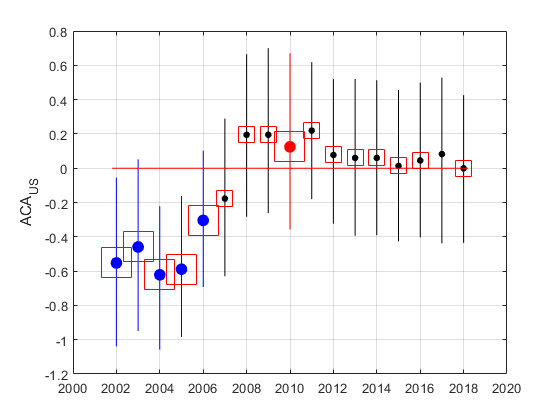

ACA_result= all_trend_STN(ACA_tr,ACA_st); 

ACA_result_D=ACA_result;

ACA_result_19y= trend_STN_2000_2018(ACA_tr,ACA_st);